# Difference of Gaussians

## How it works

A gaussian blur is applied to an image two times and the difference of them is taken. The result is an image with its edges highlighted.

### 
$$G_{\sigma } -G_{k\sigma }$$


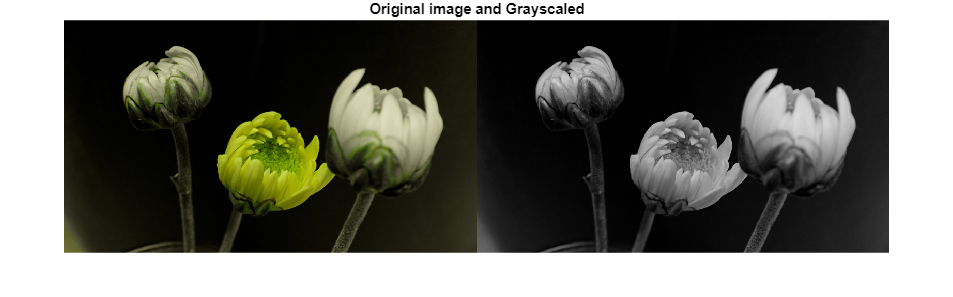

buds = imread("assets\images\blooming_buds.jpg");
buds = im2double(buds); % normalize image
gray_buds = rgb2gray(buds); % grayscale image
montage({buds, gray_buds});
title("Original image and Grayscaled");

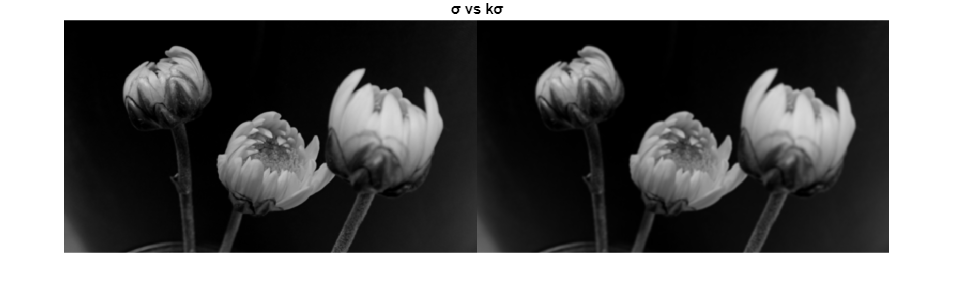

sigma =5; % sigma (σ)
k = 1.6;
G_sig = imgaussfilt(gray_buds, sigma);
G_k_sig = imgaussfilt(gray_buds, k*sigma);
dog = G_sig - G_k_sig;
montage({G_sig, G_k_sig});
title("σ vs kσ");

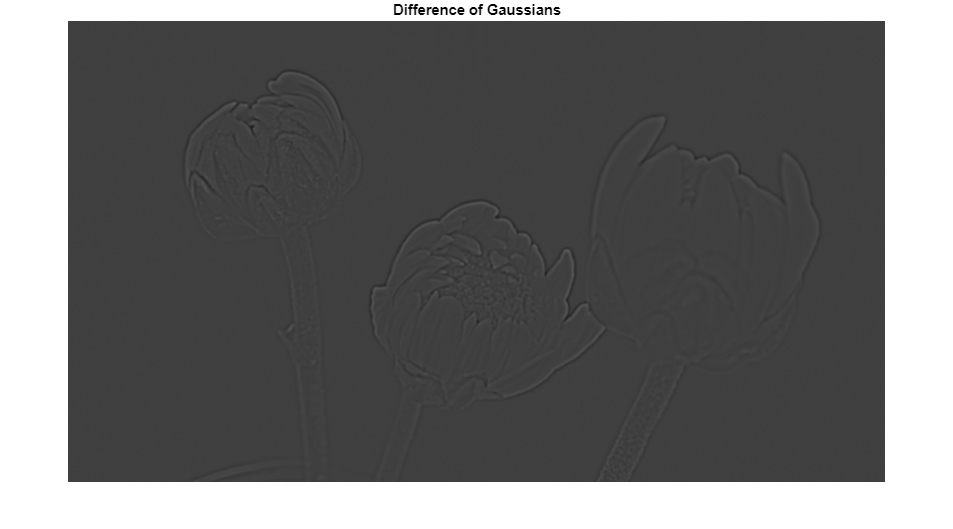

% the DoG exposure is increased by 0.25 to better see the result
imshow(dog + 0.25);
title("Difference of Gaussians");

We can apply a threshold which results in a binary image.

### 
$$T_{\varepsilon } \left(u\right)=\left\lbrace \begin{array}{ll}
1 & u\ge \varepsilon \\
0 & \textrm{otherwise}
\end{array}\right.$$


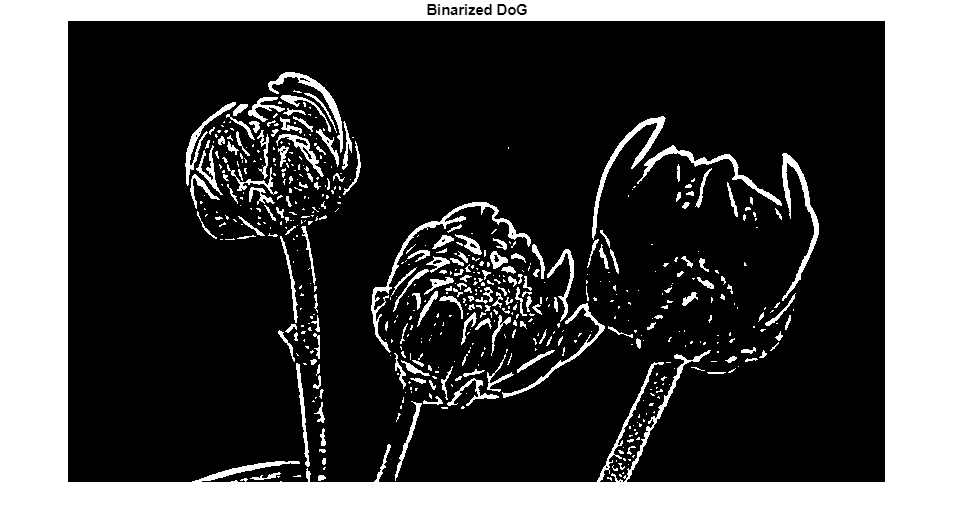

% Threshold
thresh =0.00625; % epsilon (ε)
bin_dog = dog;
bin_dog(bin_dog >= thresh) = 1;
bin_dog(bin_dog < thresh) = 0;

imshow(bin_dog);
title("Binarized DoG");

clear dog bin_dog buds gray_buds thresh;

# Extending DoG

We continue from the Difference of Gaussians and try to generalize and extend it in an aesthetic way. We try to derive some styles such as pencil-shading, pastel, hatching and woodcut as well as a range of subtle artistic effects.

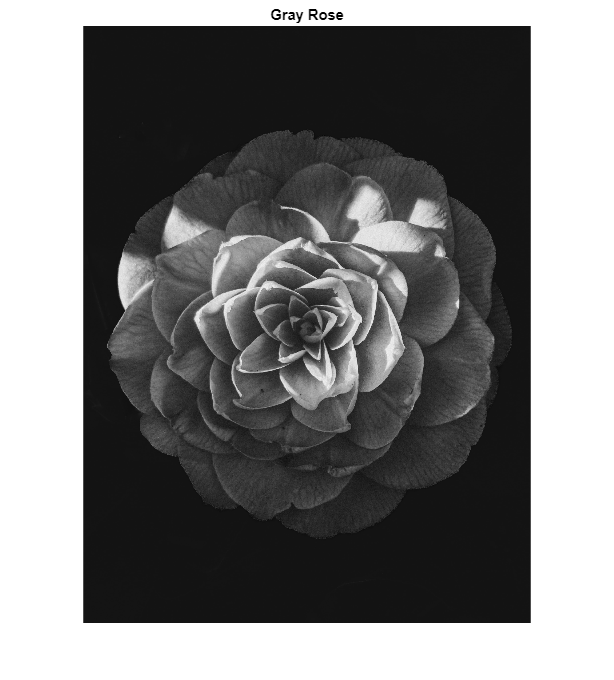

gray_rose = imread("assets\images\gray_rose.jpg");
gray_rose = im2double(gray_rose); % normalize image
gray_rose = rgb2gray(gray_rose); % grayscale image
imshow(gray_rose);
title("Gray Rose");

## Edge emphasis stregnth

We start by introducing $\tau$ (tau) as a scalar to the ${\mathit{\mathbf{G}}}_{\mathit{\mathbf{k}}\sigma }$

### 
$$G_{\sigma } -\tau \cdot G_{k\sigma }$$


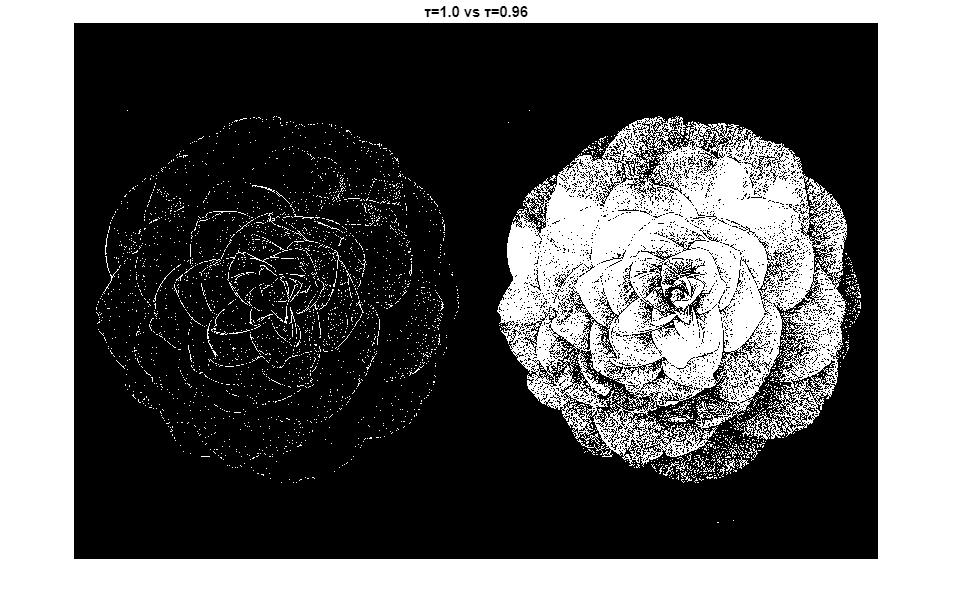

sigma =1.4; % sigma (σ)
tau =0.96; % tau (τ)
k = 1.6;

G_sig = imgaussfilt(gray_rose, sigma);
G_k_sig = imgaussfilt(gray_rose, k*sigma);

dog_1 = G_sig - 1.0*G_k_sig;
dog_tau = G_sig - tau*G_k_sig;

% Binary Threshold
eps =0.0075; % epsilon (ε)
dog = [dog_1, dog_tau];
dog(dog >= eps) = 1;
dog(dog < eps) = 0;

imshow(dog);
title(sprintf("τ=1.0 vs τ=%.2f", tau));

## Smooth thresholding

We can use a smooth thresholding function

### 
$$T_{\varepsilon ,\varphi } \left(u\right)=\left\lbrace \begin{array}{ll}
1 & u\ge \varepsilon \\
1+\tanh \left(\varphi \cdot \left(u-\varepsilon \right)\right) & \textrm{otherwise}
\end{array}\right.$$


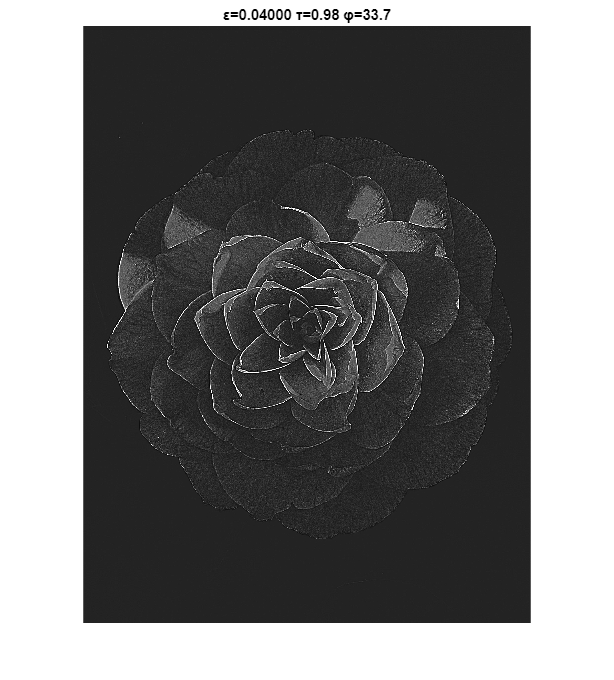

eps =0.04; % epsilon (ε)
phi =33.7; % phi (φ)
tau =0.98; % tau (τ)

% Smooth Threshold
dog = G_sig - tau*G_k_sig;
dog(dog >= eps) = 1;
dog(dog < eps) = 1 + tanh(phi*(dog(dog < eps) - eps));
imshow(dog);
title(sprintf("ε=%.5f τ=%.2f φ=%.1f",eps, tau, phi));

clear tau dog_tau dog_1;

## Reparameterization for better control

As we increase $\tau$ the average brightness of the image decresses. However increasing $\tau$ is the only way of increasing emphasis on edge lines. Thus, in order to create XDoG outputs having different edge emphasis strengths but same average brightness, any adjustments to $\tau$ must be coupled with adjusting $\varphi$ and $\varepsilon$.

After reparameterization we derive this eqation:

### 
$$\left(1+p\right){\cdot G}_{\sigma } -p\cdot G_{k\sigma }$$


Refer to `eXtended_difference_of_gaussians` eqation 7 reference for more information.

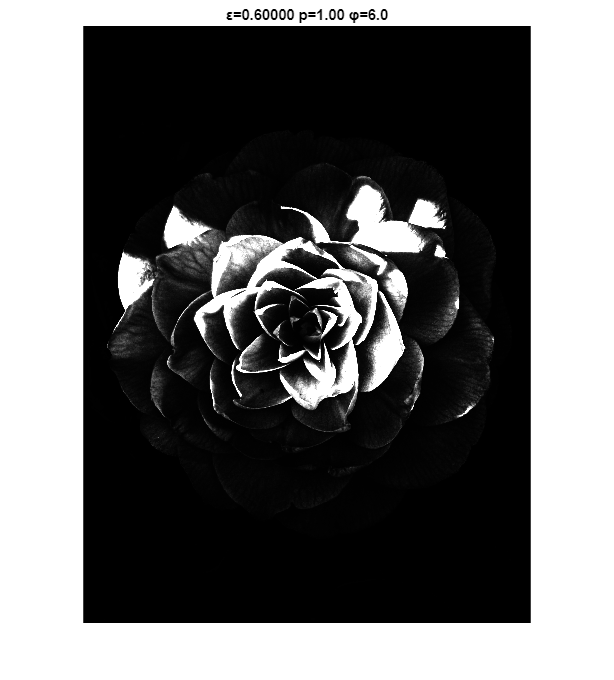

eps =0.6; % epsilon (ε)
phi =6; % phi (φ)
p =1; % p

% Smooth Threshold
dog = (1+p)*G_sig - p*G_k_sig;
dog(dog >= eps) = 1;
dog(dog < eps) = 1 + tanh(phi*(dog(dog < eps) - eps));
imshow(dog);
imwrite([dog, gray_rose], 'gray_rose.jpg', 'jpg', Quality=100);
title(sprintf("ε=%.5f p=%.2f φ=%.1f",eps, p, phi));

clear gray_rose dog;

## The Noise problem

Altough we have control over the sharpness we still need to work on the noise produced by the effect suppose the image bellow

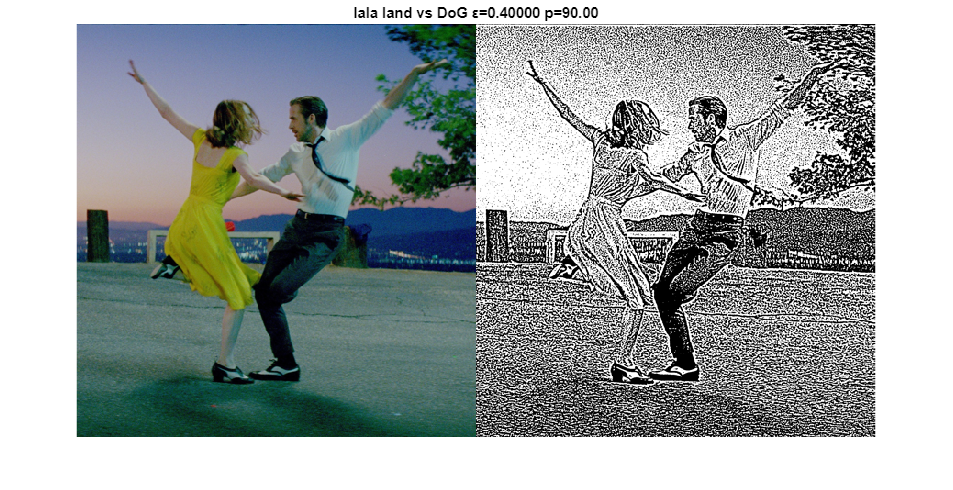

lala_land = imread("assets\images\lala_land.jpg");
lala_land = im2double(lala_land); % Normalize image
gray_lala_land = rgb2gray(lala_land);
% Apply XDoG
sigma = 2; % sigma (σ)
p = 90; % p
k = 1.6;

G_sig = imgaussfilt(gray_lala_land, sigma);
G_k_sig = imgaussfilt(gray_lala_land, k*sigma);

% Binary Threshold
eps = 0.4; % epsilon (ε)
dog = (1+p)*G_sig - p*G_k_sig;
dog(dog >= eps) = 1;
dog(dog < eps) = 0;
montage({lala_land dog});
title(sprintf("lala land vs DoG ε=%.5f p=%.2f",eps, p));

### Edge Tangent Flow Map

We start by calculating the Edge-Tangent-Flow or `ETF` of the image using Sobel filter and the `Structure Tensor` which is smoothed using gaussian blur with sigma of $\sigma_c$.

## 
$$S=\left\lbrack \begin{array}{cc}
D_x *D_x  & D_x *D_y \\
D_x *D_y  & D_y *D_y 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
E & F\\
F & G
\end{array}\right\rbrack$$


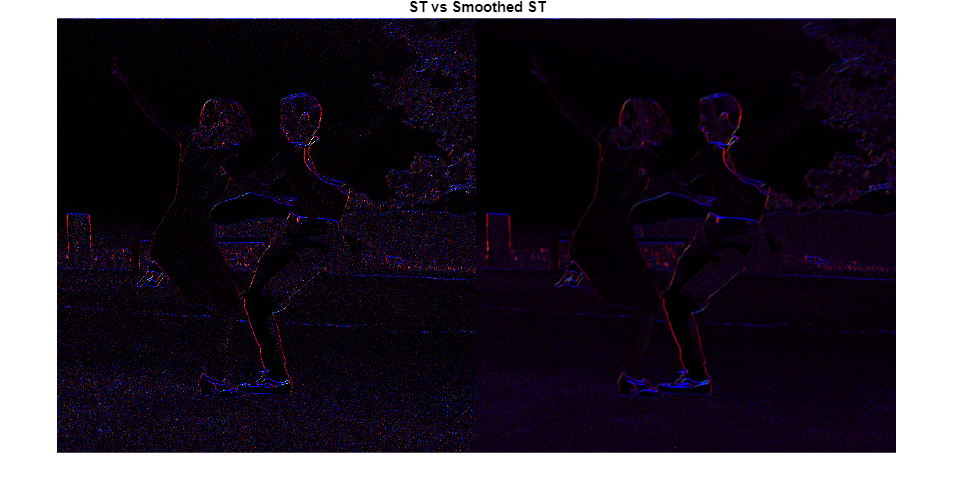

% Calculate Partial Derivatives of Image using Sobel Operator
[Dx, Dy] = imgradient(lala_land);
ST = cat(3, dot(Dx,Dx,3), dot(Dx,Dy,3), dot(Dy,Dy,3)); % Structure Tensor (E, F, G)
sigma_c =2.4; % structure tensor deviation
SST = imgaussfilt(ST,sigma_c); % Blured/Smoothed Structure Tensor
imshow([ST,SST].*10);
title("ST vs Smoothed ST");

Now we calculate the eigenvalue and eigenvector which points to the direction of least change [refer to `image_abstraction_by_structure_adaptive_filtering sec 3.1`]

### 
$$\begin{array}{l}
\lambda_{1,2} =\frac{E+G\pm \sqrt{{\left(E-G\right)}^2 +4F^2 }}{2}\\
v_2 =\left\lbrack \begin{array}{c}
\lambda_2 -G\\
F
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\lambda_1 -E\\
-F
\end{array}\right\rbrack 
\end{array}$$


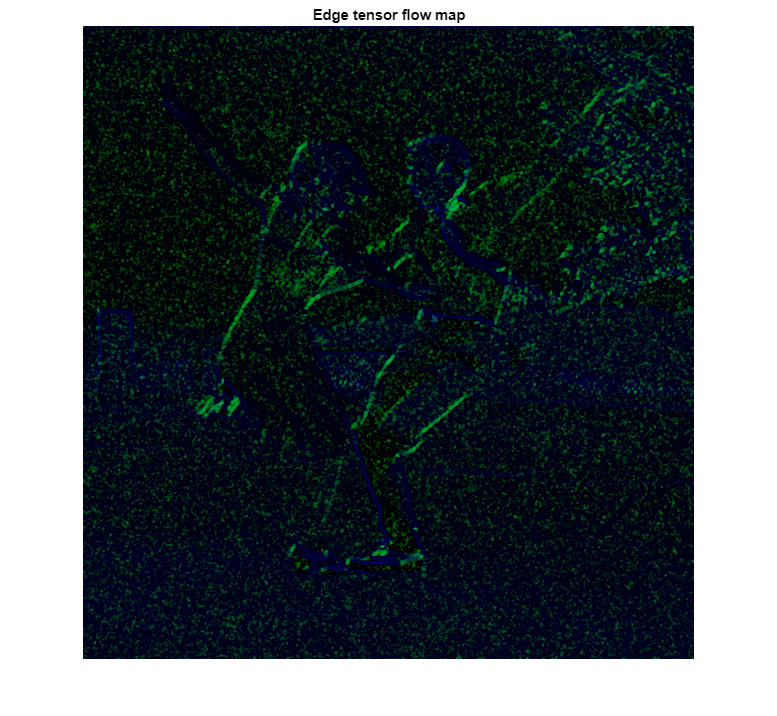

lambda_1 = (SST(:,:,1)+SST(:,:,3)+sqrt((SST(:,:,1)-SST(:,:,3)).^2+4.0*SST(:,:,1).^2))*0.5;
v_2 = cat(3, SST(:,:,1) - lambda_1, SST(:,:,2));
v_2 = matnorm(v_2); % Normalaize [x y]
ETFM = cat(3,v_2,sqrt(lambda_1)); % sqrt(lambda_1) is maximum rate of change
imshow(ETFM);
title("Edge tensor flow map");

From now on we use the `im2etf` function to calculate the ETF of the image.

clear ETFM lambda_1 v_2 SST ST sigma dog G_sig G_k_sig;

After calculating the ETF we apply directional gaussian blur with sigma of $\sigma_e$ perpendicular to the tangent vector in both directions. Then for each pixel we follow along the vectors in our kernel and apply gaussian blur with sigma of $\sigma_e$ in both directions.

# Functions

**Edge Tangent Flow**

function J = im2etf(I, sigma_c)
[Dx, Dy] = imgradient(I);
S = cat(3, dot(Dx,Dx,3), dot(Dx,Dy,3), dot(Dy,Dy,3)); % Structure Tensor (E, F, G)
S = imgaussfilt(S,sigma_c); % Blured/Smoothed Structure Tensor

lambda_1 = (S(:,:,1)+S(:,:,3)+sqrt((S(:,:,1)-S(:,:,3)).^2+4.0*S(:,:,1).^2))*0.5;
v_2 = cat(3, S(:,:,1) - lambda_1, S(:,:,2));
v_2 = matnorm(v_2); % Normalaize [x y]
J = cat(3,v_2,sqrt(lambda_1)); % sqrt(lambda_1) is maximum rate of change
end

**Image gradient using sobel operator**

function [Gx, Gy] = imgradient(I)
sobel_kernel = fspecial("sobel");
Gy = imfilter(I,sobel_kernel,"replicate","same","conv");
Gx = imfilter(I,sobel_kernel',"replicate","same","conv");
% normalize
Gy = Gy / 4.0;
Gx = Gx / 4.0;
end

**Gaussian Filter**

function h = gaussianfilter(sigma)
% generate gaussian blur kernel
kernel_radius = max(1, floor(sigma*2.45));
[X,Y] = meshgrid(-kernel_radius:kernel_radius, -kernel_radius:kernel_radius);
h = (1.0/sqrt(2.0*pi*sigma*sigma))*exp(-(X.*X + Y.*Y)/(2.0*sigma*sigma));
% normalize
h_sum = sum(h(:));
if h_sum ~=0
    h = h./h_sum;
end
end

function J = imgaussfilt(I, sigma)
% convolve image with gaussian blur of sigma
guassian_kernel = gaussianfilter(sigma);
J = imfilter(I,guassian_kernel,"replicate","same","conv");
end

**Normalize Matrix**

function N = matnorm(M)
X = M(:,:,1);
Y = M(:,:,2);
MAG = sqrt(X.*X + Y.*Y);
X = X./MAG;
Y = Y./MAG;
X(X == Inf) = 0.0;
Y(Y == Inf) = 1.0;
N = cat(3, X, Y);
end